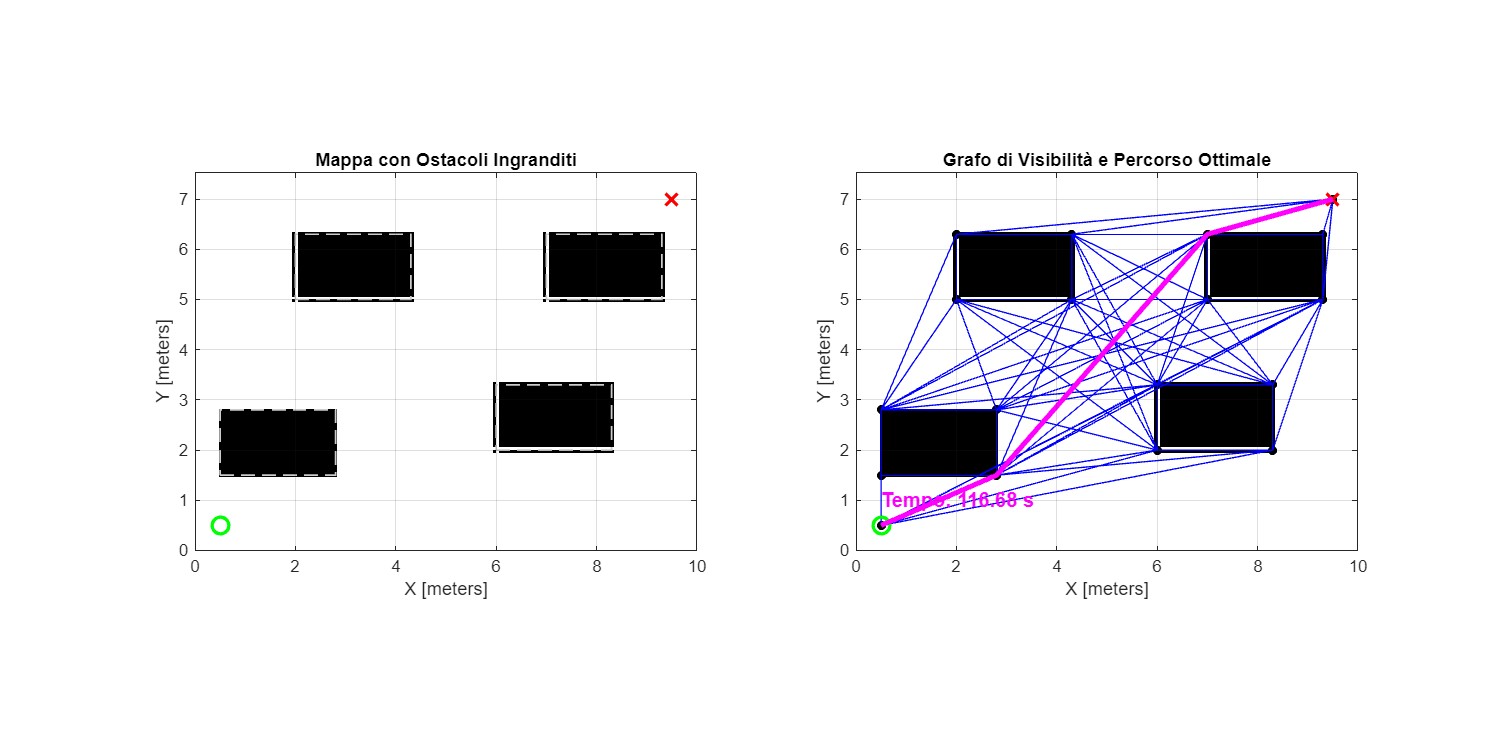


clear; clc; close all;

%% === Parametri Robot ===
rRuota = 0.05;     % raggio ruota
dRuote = 0.26;     % distanza ruote
v_max = 0.1;       % velocità lineare massima
omega_max = v_max / (dRuote/2);  % velocità angolare massima

%% === Mappa e Ostacoli ===
mapWidth = 10; mapHeight = 7.5; mapResolution = 17;
map = binaryOccupancyMap(mapWidth, mapHeight, mapResolution);
robotRadius = 0.15;

% Ostacoli: [x y w h]
obstacles = [
    0.5, 1.5, 2.30, 1.30;
    6, 2, 2.30, 1.30;
    2, 5, 2.30, 1.30;
    7, 5, 2.30, 1.30
];
inflatedObstacles = obstacles;

% Inserimento ostacoli nella mappa
for i = 1:size(obstacles,1)
    rect = obstacles(i,:);
    xVals = linspace(rect(1), rect(1)+rect(3), ceil(rect(3)*mapResolution));
    yVals = linspace(rect(2), rect(2)+rect(4), ceil(rect(4)*mapResolution));
    [X,Y] = meshgrid(xVals, yVals);
    setOccupancy(map, [X(:), Y(:)], 1);
end

%% === Posa iniziale e finale ===
startPose = [0.5, 0.5, 0];
goalPose = [9.5, 7, pi];

%% === Costruzione del grafo di visibilità ===
[vertices, adjacencyMatrix, costMatrix] = createVisibilityGraph(map, inflatedObstacles, startPose, goalPose, v_max);

%% === Ricerca percorso minimo in tempo ===
[pathIndices, totalTime] = findPathWithDijkstra(vertices, adjacencyMatrix, v_max, omega_max, startPose, goalPose);

%% === Calcolo velocità trapezoidali lungo il percorso ===
Ts = 0.1;  % step temporale
[v, omega_z, omega_r, omega_l, tempo] = computeVelocitiesTrapezoidal(vertices, pathIndices, v_max, omega_max, rRuota, dRuote, Ts, goalPose);

 % Visualizzazione dei Risultati
plotResults(map, obstacles, inflatedObstacles, startPose, goalPose, vertices, adjacencyMatrix, pathIndices, totalTime);

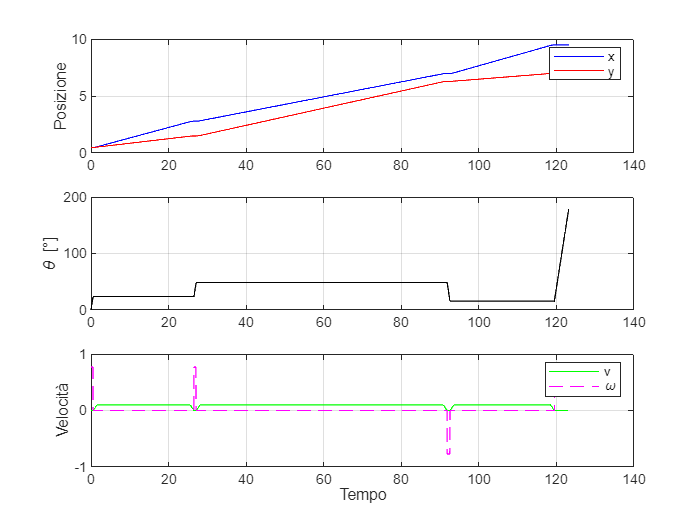

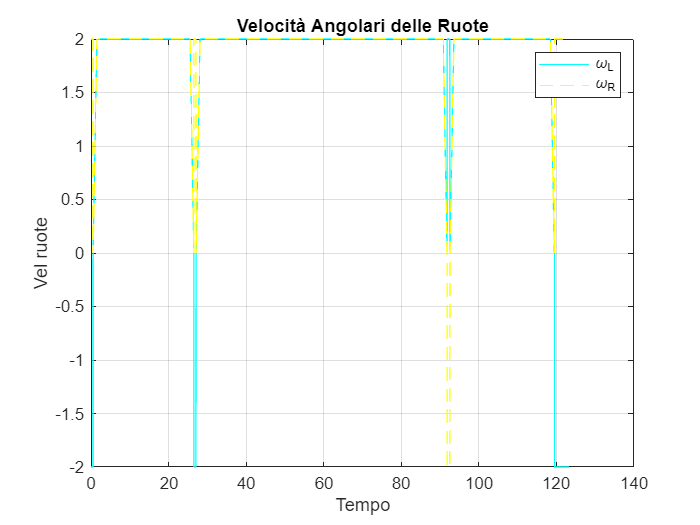


%% === Ricostruzione traiettoria ===
stati = zeros(length(tempo), 3);
x = startPose(1); y = startPose(2); theta = startPose(3);
stati(1,:) = [x y theta];

for i = 2:length(tempo)
    dt = tempo(i)-tempo(i-1);
    x = x + v(i-1)*cos(theta)*dt;
    y = y + v(i-1)*sin(theta)*dt;
    theta = theta + omega_z(i-1)*dt;
    stati(i,:) = [x y theta];
end

%% === Grafico traiettoria e velocità ===
velocita = [v omega_z];
plotCinematica(tempo, stati, velocita, omega_l, omega_r);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% ======================= FUNZIONI ======================================
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [vertices, adjMat, costMat] = createVisibilityGraph(map, obstacles, startPose, goalPose, maxV)
    vertices = [startPose(1:2); goalPose(1:2)];
    for i = 1:size(obstacles,1)
        x = obstacles(i,1); y = obstacles(i,2); w = obstacles(i,3); h = obstacles(i,4);
        vertices = [vertices;
            x y;
            x+w y;
            x y+h;
            x+w y+h];
    end
    vertices = unique(vertices, 'rows', 'stable');
    N = size(vertices,1);
    adjMat = zeros(N); costMat = inf(N);

    for i = 1:N
        for j = i+1:N
            if ~collides(vertices(i,:), vertices(j,:), obstacles)
                dist = norm(vertices(i,:) - vertices(j,:));
                time = dist / maxV;
                adjMat(i,j) = 1; adjMat(j,i) = 1;
                costMat(i,j) = time; costMat(j,i) = time;
            end
        end
    end
end

function col = collides(p1, p2, obstacles)
    col = false; N = 10;
    xs = linspace(p1(1), p2(1), N); ys = linspace(p1(2), p2(2), N);
    for i = 1:length(xs)
        for j = 1:size(obstacles,1)
            r = obstacles(j,:);
            if xs(i) > r(1) && xs(i) < r(1)+r(3) && ys(i) > r(2) && ys(i) < r(2)+r(4)
                col = true; return;
            end
        end
    end
end

function [path, totalTime] = findPathWithDijkstra(vertices, adj, v_max, omega_max, startPose, goalPose)
    N = size(vertices,1);
    dist = inf(1,N); prev = zeros(1,N); orient = zeros(1,N);
    startIdx = find(ismember(vertices, startPose(1:2), 'rows'));
    goalIdx = find(ismember(vertices, goalPose(1:2), 'rows'));
    dist(startIdx) = 0; orient(startIdx) = startPose(3);
    Q = 1:N;

    while ~isempty(Q)
        [~, idx] = min(dist(Q)); u = Q(idx); Q(idx) = [];
        if u == goalIdx, break; end
        for v = find(adj(u,:))
            p1 = vertices(u,:); p2 = vertices(v,:);
            d = norm(p2 - p1); t_lin = d / v_max;
            theta_des = atan2(p2(2)-p1(2), p2(1)-p1(1));
            dtheta = wrapToPi(theta_des - orient(u));
            t_rot = abs(dtheta) / omega_max;
            cost = t_lin + t_rot;
            if dist(u) + cost < dist(v)
                dist(v) = dist(u) + cost;
                prev(v) = u; orient(v) = theta_des;
            end
        end
    end

    path = goalIdx;
    while path(1) ~= startIdx
        path = [prev(path(1)); path];
    end
    totalTime = dist(goalIdx);
end


function [v, omega_z, omega_r, omega_l, tempo] = computeVelocitiesTrapezoidal(vertices, pathIdx, v_max, omega_max, r, d, Ts, goalPose)
    v = []; omega_z = []; omega_r = []; omega_l = []; tempo = []; t = 0;

    for i = 1:length(pathIdx)-1
        p1 = vertices(pathIdx(i), :);
        p2 = vertices(pathIdx(i+1), :);
        dx = p2(1)-p1(1); dy = p2(2)-p1(2);
        theta_des = atan2(dy, dx);

        if i==1, theta_prev = 0;
        else
            p0 = vertices(pathIdx(i-1), :);
            theta_prev = atan2(p1(2)-p0(2), p1(1)-p0(1));
        end

        % === ROTAZIONE SUL POSTO ===
        delta = wrapToPi(theta_des - theta_prev);
        t_rot = abs(delta)/omega_max;
        Trot = 0:Ts:t_rot;
        omega = sign(delta)*omega_max * ones(size(Trot));
        v_rot = zeros(size(Trot));
        w_r = (d/2 * omega) / r;
        w_l = -w_r;

        v = [v; v_rot'];
        omega_z = [omega_z; omega'];
        omega_r = [omega_r; w_r'];
        omega_l = [omega_l; w_l'];
        tempo = [tempo; t + Trot'];
        t = t + t_rot;

        % === TRASLAZIONE ===
        dist = hypot(dx, dy);
        a = 0.1;  % accelerazione
        t_a = v_max / a;
        d_a = 0.5*a*t_a^2;

        if dist < 2*d_a
            t_a = sqrt(dist/a);
            t_c = 0; d_c = 0;
        else
            d_c = dist - 2*d_a;
            t_c = d_c / v_max;
        end
        T1 = 0:Ts:t_a;
        T2 = Ts:Ts:t_c;
        T3 = Ts:Ts:t_a;

        v_prof = [a*T1, v_max*ones(1,length(T2)), v_max - a*T3];
        omega_seg = zeros(size(v_prof));
        w_r2 = v_prof ./ r;
        w_l2 = w_r2;

        v = [v; v_prof'];
        omega_z = [omega_z; omega_seg'];
        omega_r = [omega_r; w_r2'];
        omega_l = [omega_l; w_l2'];
        tempo = [tempo; (t + Ts*(0:length(v_prof)-1))'];
        t = tempo(end);
    end

    % === ROTAZIONE FINALE PER RISPETTARE LA POSA ===
    theta_finale = atan2(vertices(pathIdx(end),2)-vertices(pathIdx(end-1),2), ...
                         vertices(pathIdx(end),1)-vertices(pathIdx(end-1),1));
    delta = wrapToPi(goalPose(3) - theta_finale);
    t_rot = abs(delta)/omega_max;
    Trot = 0:Ts:t_rot;

    if t_rot > 0
        omega = sign(delta)*omega_max * ones(size(Trot));
        v_rot = zeros(size(Trot));
        w_r = (d/2 * omega) / r;
        w_l = -w_r;

        v = [v; v_rot'];
        omega_z = [omega_z; omega'];
        omega_r = [omega_r; w_r'];
        omega_l = [omega_l; w_l'];
        tempo = [tempo; t + Trot'];
    end
end


function plotResults(map, obstacles, inflatedObstacles, startPose, goalPose, vertices, adjacencyMatrix, pathIndices, totalTime)
    %figure;
    figure('Position', [100, 100, 1200, 600]);
    subplot(1,2,1);
    show(map);
    hold on;
    title('Mappa con Ostacoli Ingranditi');

    for i = 1:size(obstacles, 1)
        rectangle('Position', obstacles(i,:), 'EdgeColor', [0.8 0.8 0.8], 'LineWidth', 1, 'LineStyle', '--');
    end

    plot(startPose(1), startPose(2), 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Start');
    plot(goalPose(1), goalPose(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Goal');

   % legend({'OccupancyGrid', 'Ostacoli Originali', 'Start', 'Goal'});
    grid on;
    axis equal;
    xlim([0 map.XWorldLimits(2)]);
    ylim([0 map.YWorldLimits(2)]);

    subplot(1,2,2);
    show(map);
    hold on;
    title('Grafo di Visibilità e Percorso Ottimale');

    plot(vertices(:,1), vertices(:,2), 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k', 'DisplayName', 'Nodi Grafo');

    for i = 1:size(adjacencyMatrix, 1)
        for j = i+1:size(adjacencyMatrix, 2)
            if adjacencyMatrix(i, j) == 1
                plot([vertices(i,1), vertices(j,1)], [vertices(i,2), vertices(j,2)], 'b-', 'LineWidth', 0.5, 'DisplayName', 'Archi Visibili');
            end
        end
    end

    plot(startPose(1), startPose(2), 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Start');
    plot(goalPose(1), goalPose(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Goal');

    if ~isempty(pathIndices)
        pathCoords = vertices(pathIndices, :);
        plot(pathCoords(:,1), pathCoords(:,2), 'm-', 'LineWidth', 3, 'DisplayName', 'Percorso Ottimale');
        text(pathCoords(1,1), pathCoords(1,2) + 0.5, ['Tempo: ', num2str(totalTime, '%.2f'), ' s'], ...
             'Color', 'm', 'FontSize', 12, 'FontWeight', 'bold');
    end
   % legend show;
    grid on;
    axis equal;
    xlim([0 map.XWorldLimits(2)]);
    ylim([0 map.YWorldLimits(2)]);

end

function plotCinematica(tempo, stati, velocita, omegaL, omegaR)
    figure;
    subplot(3,1,1);
    plot(tempo, stati(:,1), 'b', tempo, stati(:,2), 'r');
    legend('x','y'); ylabel('Posizione'); grid on;

    subplot(3,1,2);
    plot(tempo, rad2deg(stati(:,3)), 'k'); ylabel('\theta [°]'); grid on;

    subplot(3,1,3);
    plot(tempo, velocita(:,1), 'g', tempo, velocita(:,2), 'm--');
    legend('v','\omega'); ylabel('Velocità'); grid on; xlabel('Tempo');

    figure;
    plot(tempo, omegaL, 'c', tempo, omegaR, 'y--');
    legend('\omega_L','\omega_R'); ylabel('Vel ruote'); grid on; xlabel('Tempo');
    title('Velocità Angolari delle Ruote');
end
